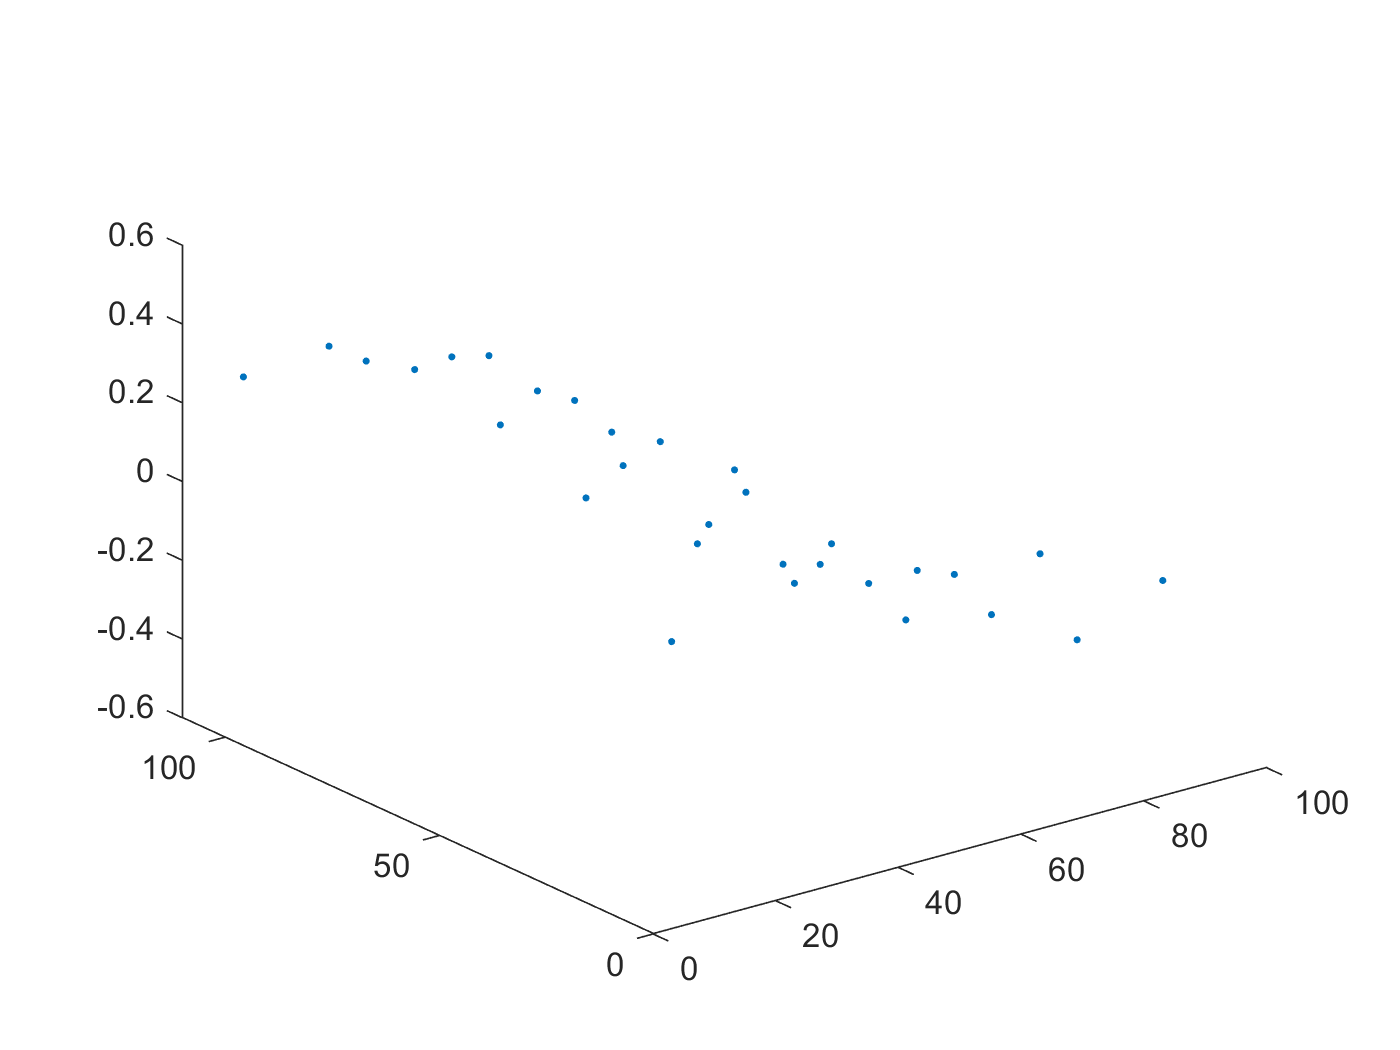

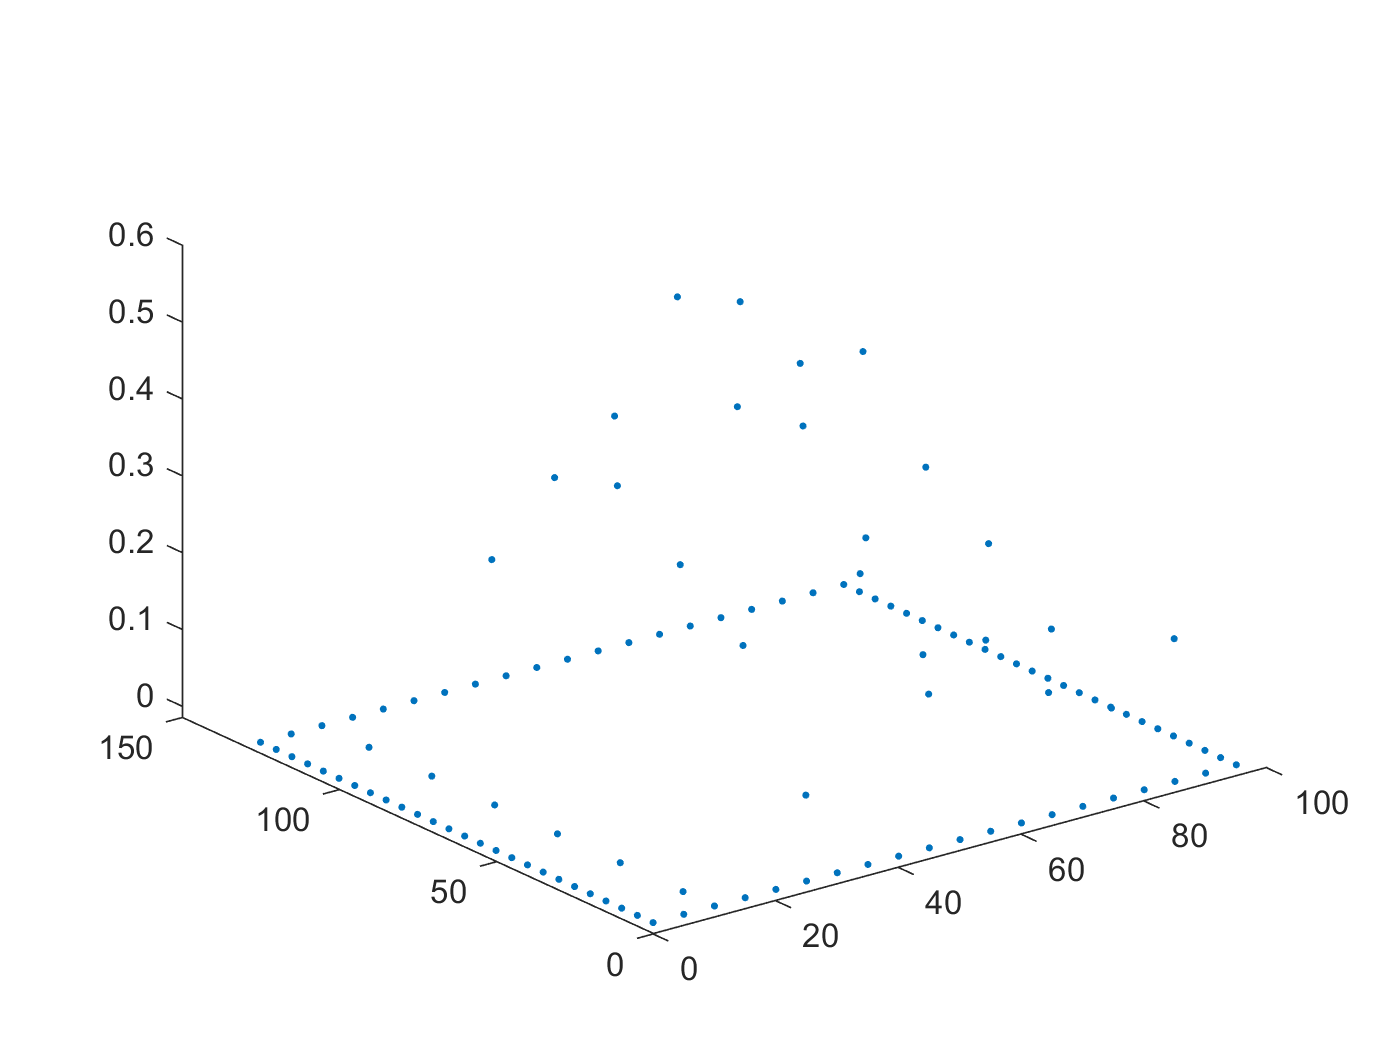

xlin = 0 : 0.1 : 95;
ylin = 0 : 0.1 : 125;
[xm, ym] = meshgrid(xlin, ylin);
pr1 = inppdata("0602a.txt", @(x) inpp1(x, 5, 5));

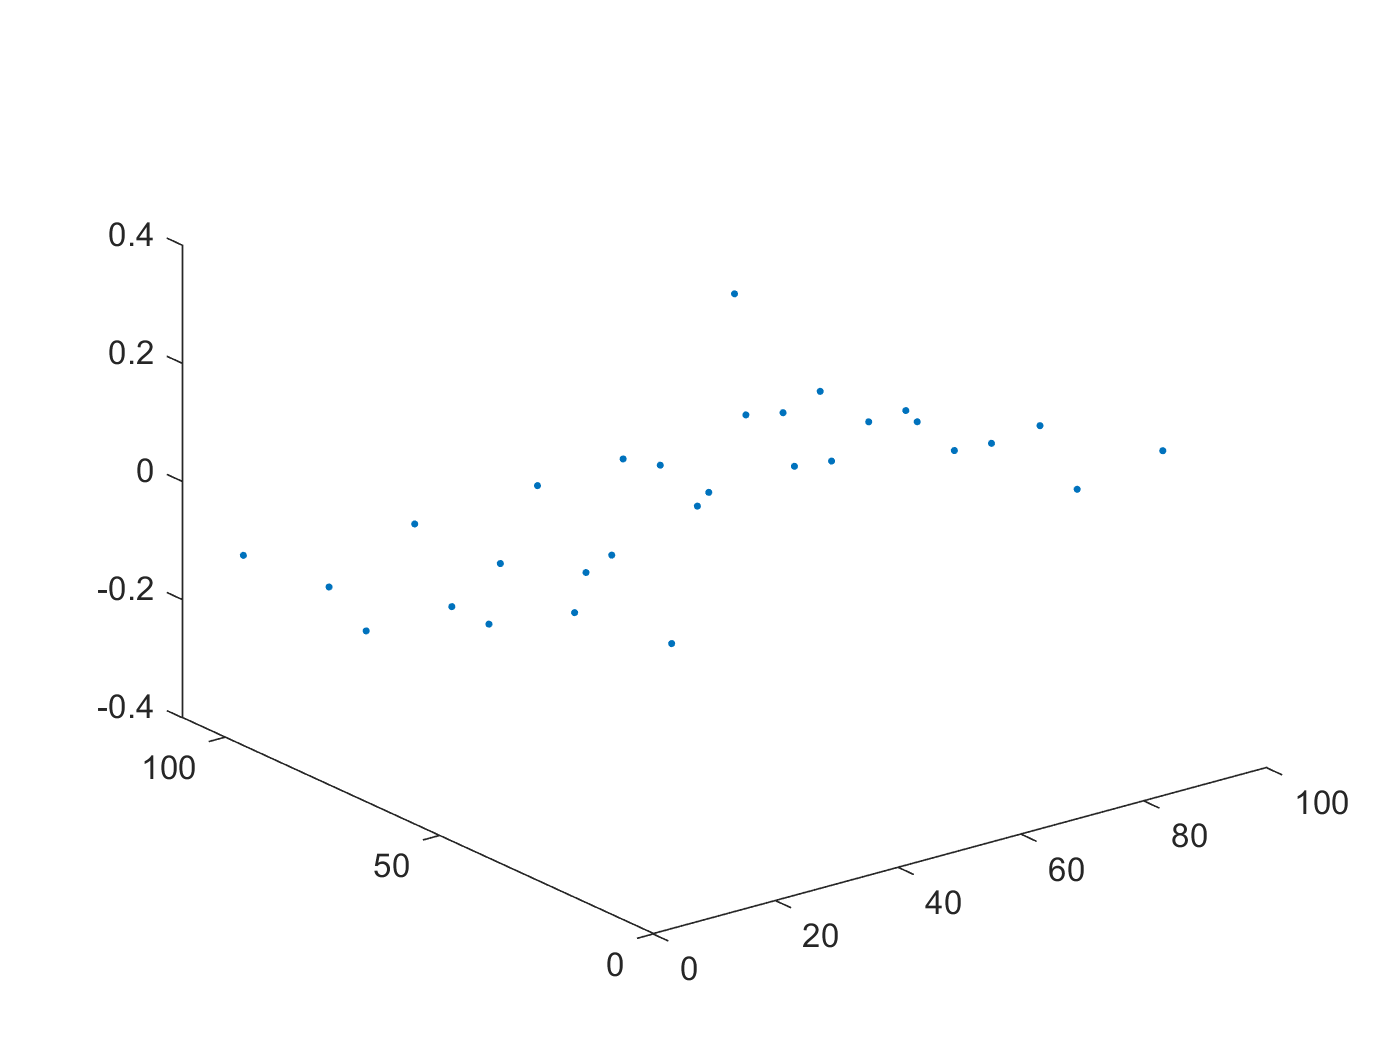

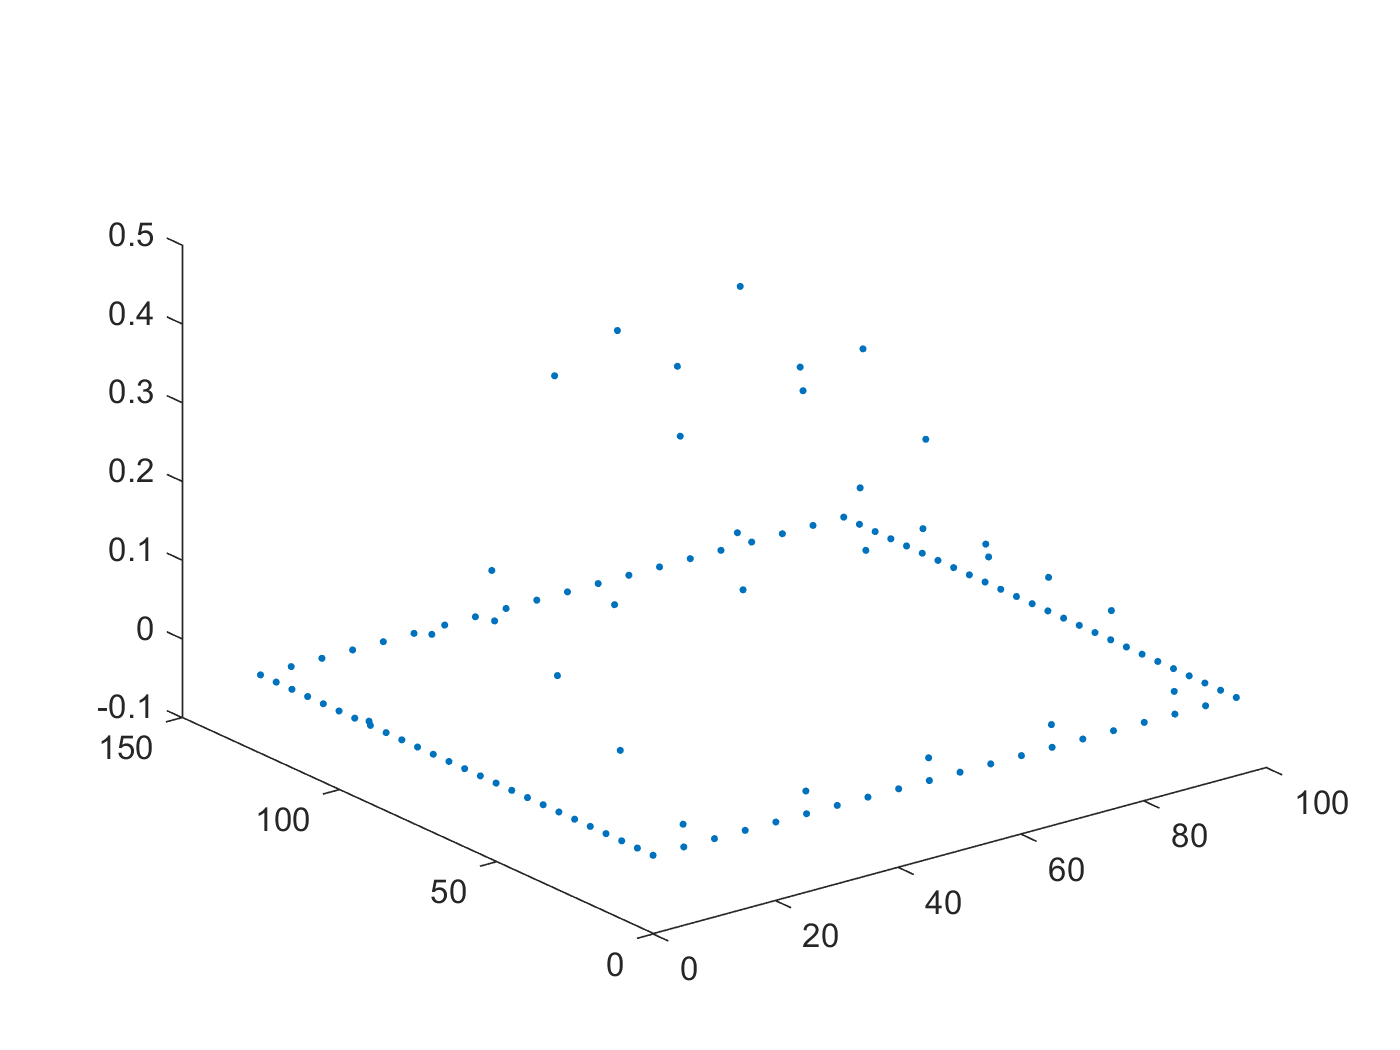

pr2 = inppdata("0602b.txt", @(x) inpp1(x, 4, 6));

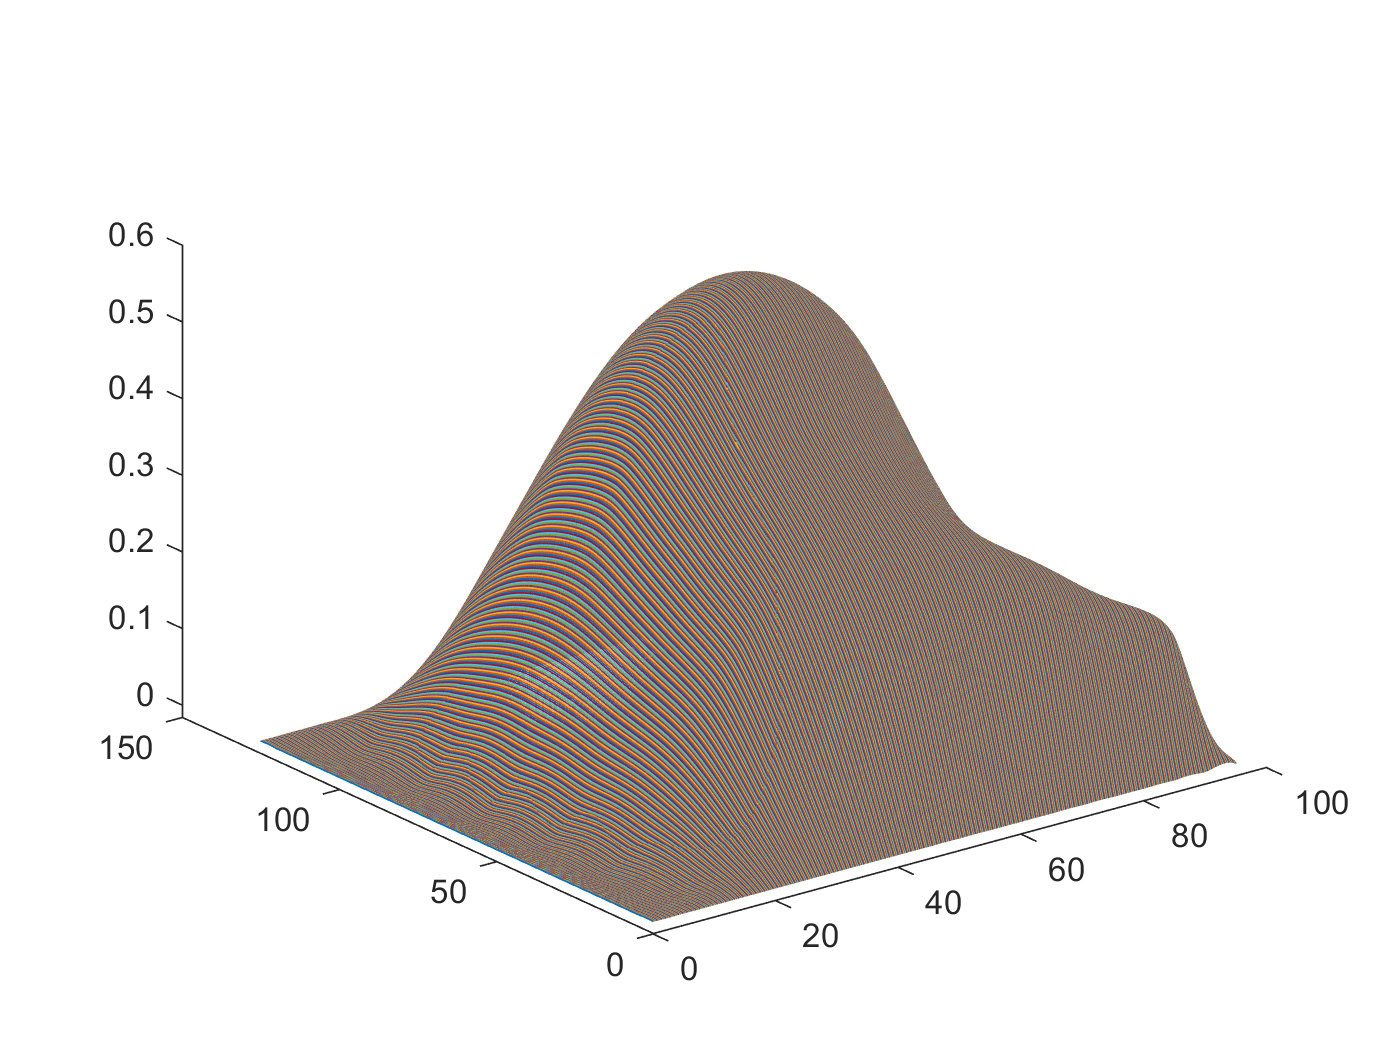

pp1 = pr1(xm, ym);
pp2 = pr2(xm, ym);
pend = (pp1 + pp2 ) ./ 2;
%plot3(xm, ym, pr1(xm, ym));
%plot3(xm, ym, pr2(xm, ym));
plot3(xm, ym, pp1);

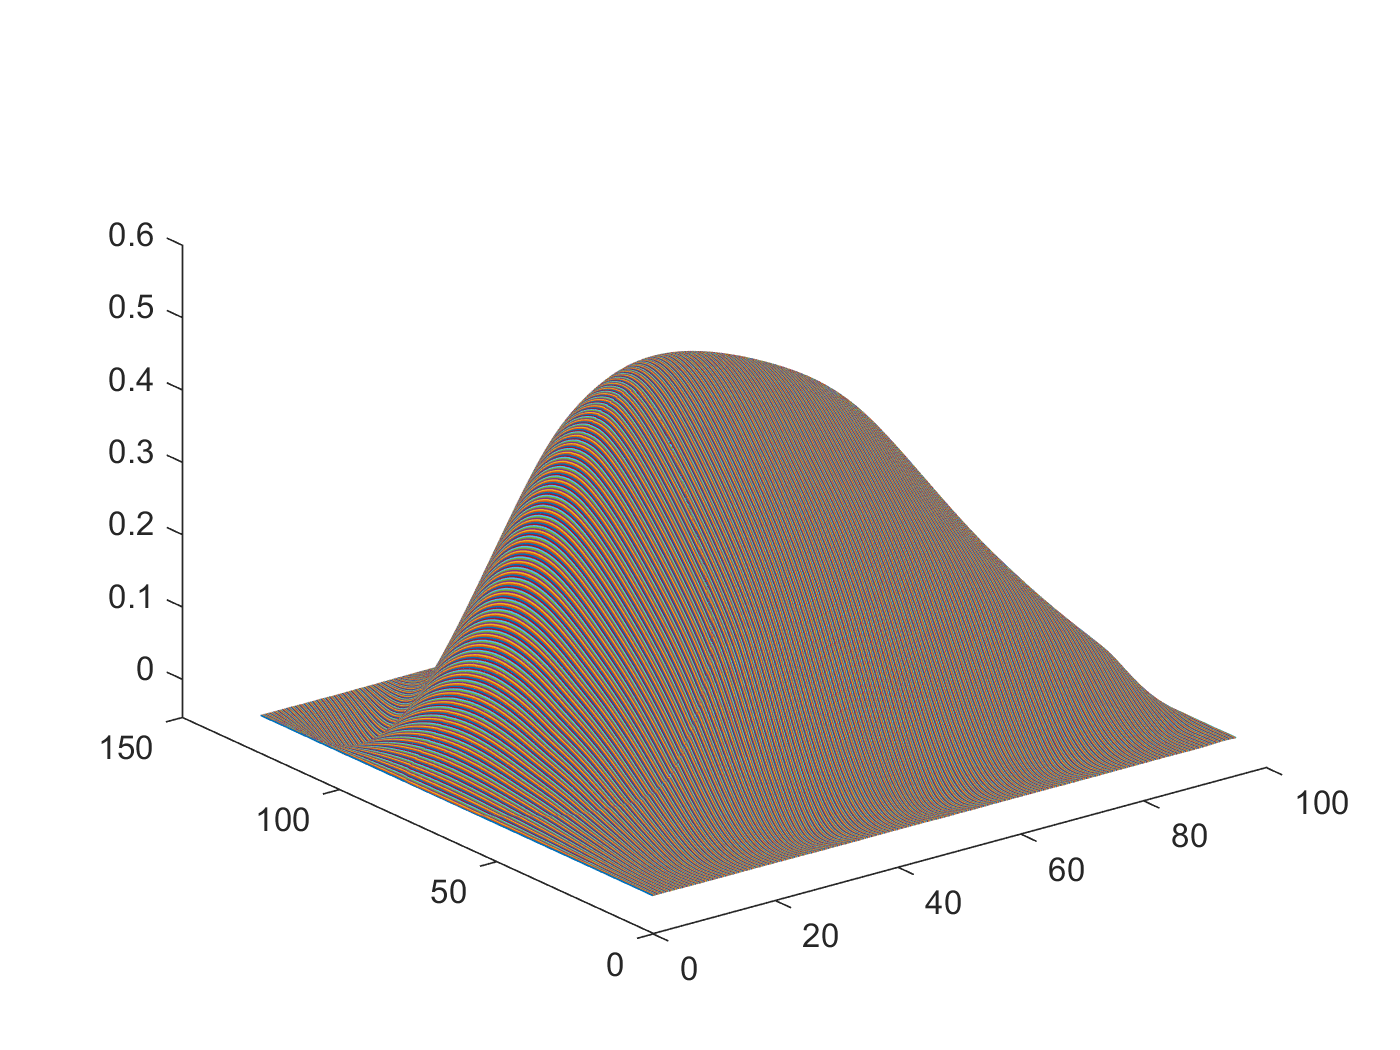

plot3(xm, ym, pp2);

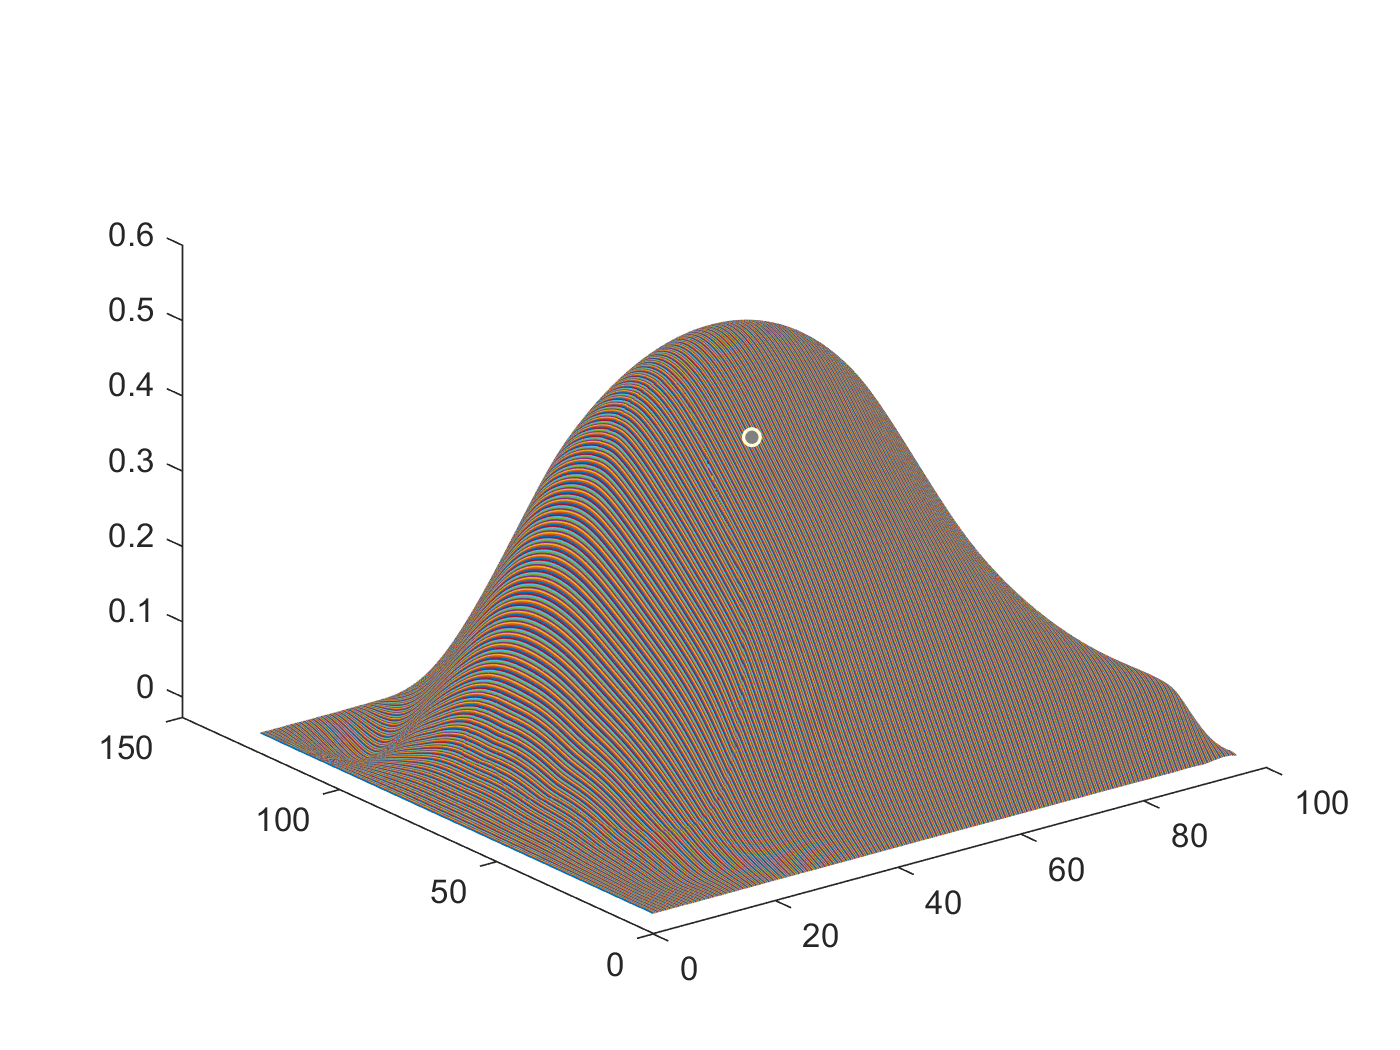

plot3(xm, ym, pend);

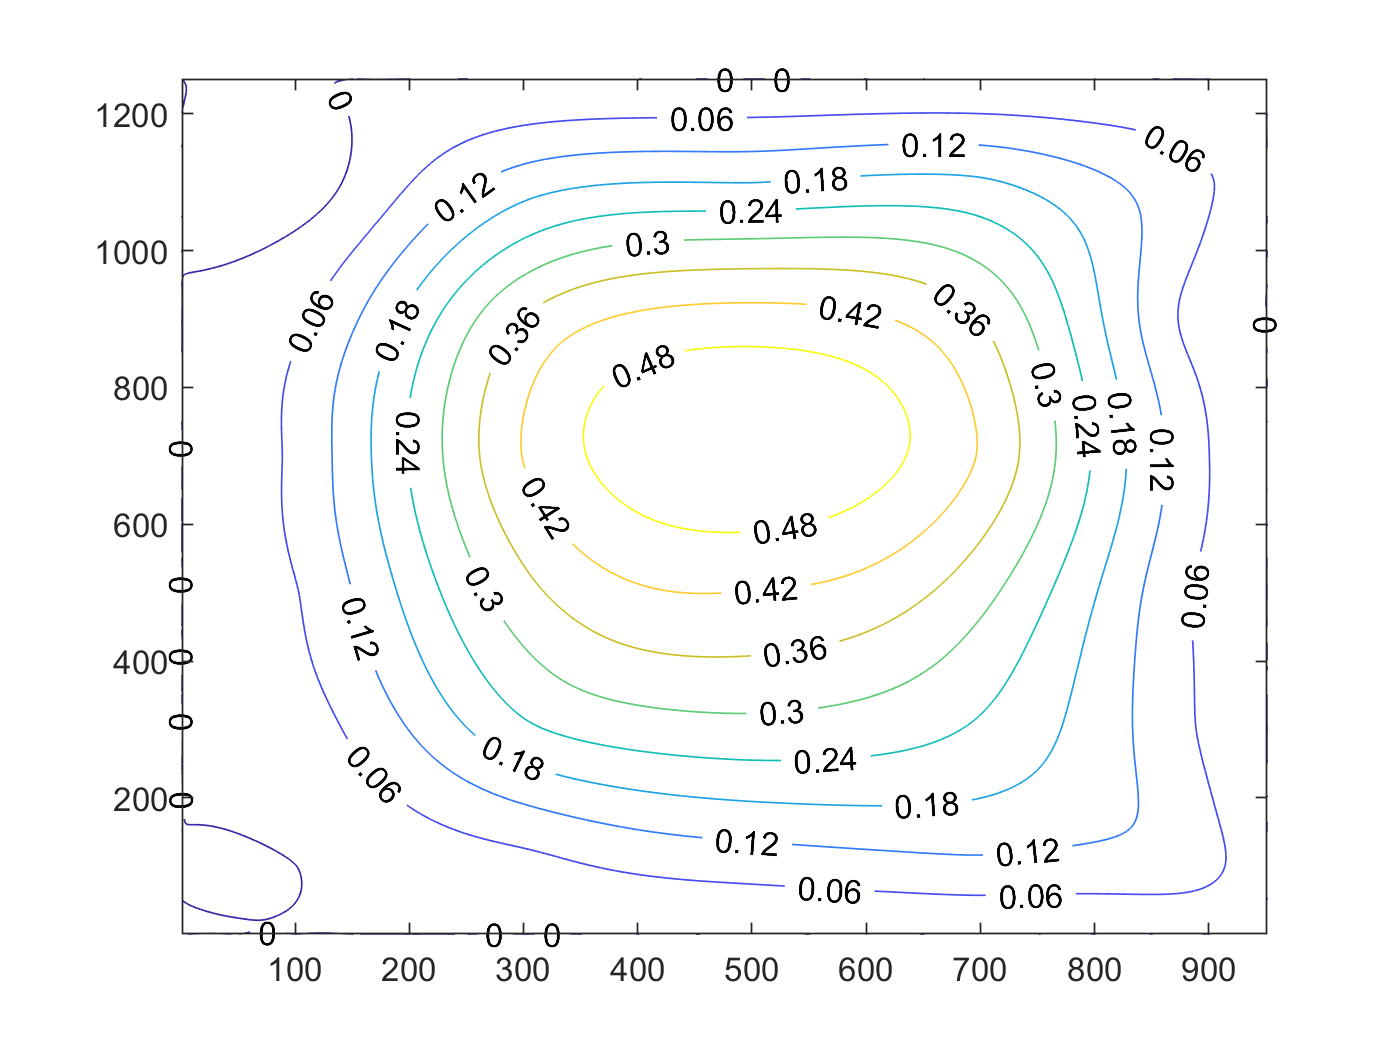


contour(pend, 0:0.06:0.6, "ShowText", "on");

function surface = inppdata(filename, fun2)
    plugData = importdata("0602c.txt");
    preData = importdata(filename);
    rawData.x = preData(1:end, 1);
    rawData.x = [rawData.x(~ isnan(rawData.x)) ; plugData(:, 1)];
    rawData.y = preData(1:end, 2);
    rawData.y = [rawData.y(~ isnan(rawData.y)) ; plugData(:, 2)];
    rawData.z = preData(1:end, 3);
    plot3(rawData.x(1:30), rawData.y(1:30), rawData.z(~ isnan(rawData.z)), '.');
    figure();
    %{
    if fun1
        quiver3(rawData.x(1:30), rawData.y(1:30), fun1(rawData.z(~ isnan(rawData.z)), ones(30, 1)));
    else
        quiver3(rawData.x(1:30), rawData.y(1:30), ones(30, 1), fun1(rawData.z(~ isnan(rawData.z))));
    end
    %}
    rawData.z = [fun2(rawData.z(~ isnan(rawData.z))) ; plugData(:, 3)];
    plot3(rawData.x, rawData.y, rawData.z, '.');
    [rawData.xF, rawData.yF, rawData.zF] = prepareSurfaceData(rawData.x, rawData.y, rawData.z);
    ft = 'biharmonicinterp';
    surface = fit( [rawData.xF, rawData.yF], rawData.zF, ft, 'Normalize', 'on' );
end

function aans = inpp1(ist, ilim, jlim)
    for i = 0 : 1 : ilim
        ist(jlim * i + 1 : jlim * (i + 1)) = cumtrapz(ist(jlim * i + 1 : jlim * (i + 1)));
    end
    aans = ist;
end